%Paper implementation

**Possible Mechanisms for the Regulation of Telomere Length (A. Kowald)**

% Parameters
% scaling factor
s_CAPf = 0.25; s_CAPb = 20; s_T = 300; s_SSL = 45; s_Oex = 0.5; s_Oin = 0.5; s_TL = 0.1;
% Initial Parameters
xin = [170; 0; 0.05; 1; 0; 0; 1000];
K3 = 5;
K5 = 500;
K6 = 10;
B = 1; % Block

Figure 4 Constant Telomere Length

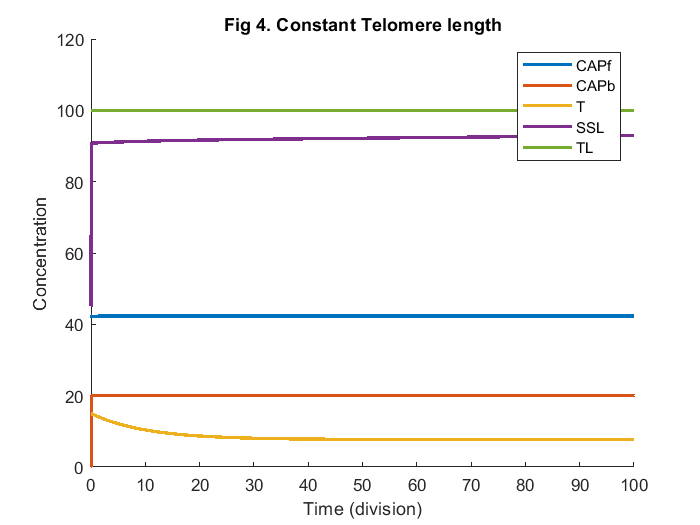

% Fig 4 Constant length
time = 0:0.01:100;
[tSol, xSol] = ode45(@(t,x) extendedModel(t,x,K3,K5,K6,B), time, xin);
figure(4); hold on;
a1 = plot(tSol,s_CAPf*xSol(:,1),'LineWidth',2); M1 = "CAPf";
a2 = plot(tSol,s_CAPb*xSol(:,2),'LineWidth',2); M2 = "CAPb";
a3 = plot(tSol,s_T*xSol(:,3),'LineWidth',2); M3 = "T";
a4 = plot(tSol,s_SSL*xSol(:,4),'LineWidth',2); M4 = "SSL";
a7 = plot(tSol,s_TL*xSol(:,7),'LineWidth',2); M7 = "TL";
legend([a1 a2 a3 a4 a7], [M1 M2 M3 M4 M7]);
xlabel("Time (division)");
ylabel("Concentration");
title('Fig 4. Constant Telomere length');
% xlim([0 100]);
 ylim([0 120]);


ss_CAPf = xSol(end,1);
ss_CAPb = xSol(end,2);
ss_T = xSol(end,3);
ss_SSL = xSol(end,4);
ss_TL = xSol(end,7);

Figure 5 Telomere Length Increases

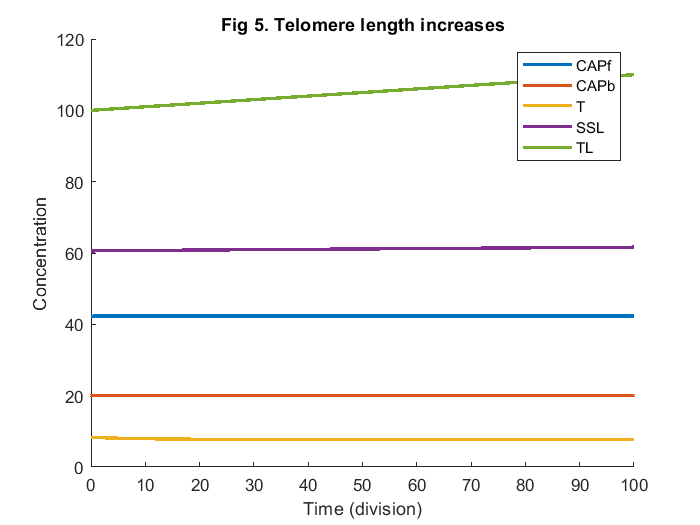

s_CAPf = 0.25; s_CAPb = 20; s_T = 300; s_SSL = 30; s_Oex = 0.5; s_Oin = 0.5; s_TL = 0.1;
xin = [169.1246; 0.9998; 0.0277; 2.0199; 0; 0; 1000.00];
%xin = [170; 0; 0.025; 2.0996; 0; 0; 1000];
%xin = [ss_CAPf; ss_CAPb; ss_T; ss_SSL; 0; 0; ss_TL];
time = 0:0.01:100;
K3 = 5;
K5 = 500;
B  = 0;
[tSol, xSol] = ode45(@(t,x) extendedModel(t,x,K3,K5,K6,B), time, xin);

figure(5); hold on;
a1 = plot(tSol,s_CAPf*xSol(:,1),'LineWidth',2); M1 = "CAPf";
a2 = plot(tSol,s_CAPb*xSol(:,2),'LineWidth',2); M2 = "CAPb";
a3 = plot(tSol,s_T*xSol(:,3),'LineWidth',2); M3 = "T";
a4 = plot(tSol,s_SSL*xSol(:,4),'LineWidth',2); M4 = "SSL";
a7 = plot(tSol,s_TL*xSol(:,7),'LineWidth',2); M7 = "TL";
legend([a1 a2 a3 a4 a7], [M1 M2 M3 M4 M7]);
xlabel("Time (division)");
ylabel("Concentration");

title('Fig 5. Telomere length increases');
% xlim([0 100]);
ylim([0 120]);

Figure 6 Inhibition of Telomerase activity

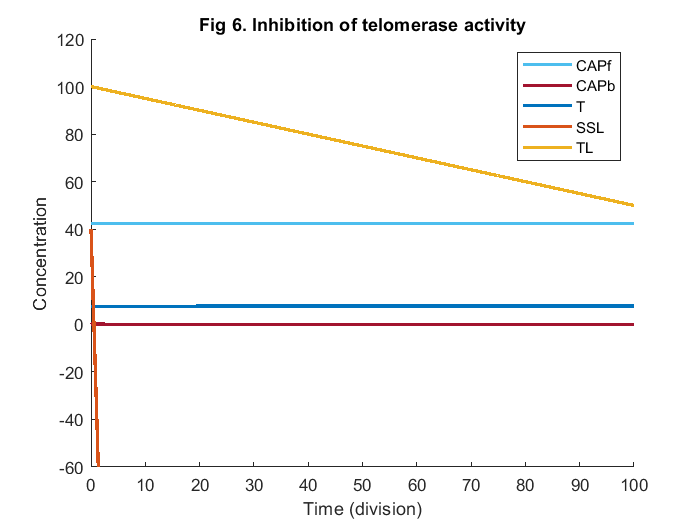

% Figure 6
s_CAPf = 0.25; s_CAPb = 20; s_T = 300; s_SSL = 20; s_Oex = 0.5; s_Oin = 0.5; s_TL = 0.1;
%xin = [169.1246; 0.9998; 0.0477; 2.0199; 0; 0; 1000.51];
xin = [170; 0; 0.025; 2.01; 0; 0; 1000];
%xin = [ss_CAPf; ss_CAPb; ss_T; ss_SSL; 0; 0; ss_TL];
time = 0:0.01:100;
K3 = 0.01;
K5 = 250;
B = 4;
[tSol, xSol] = ode45(@(t,x) extendedModel(t,x,K3,K5,K6,B), time, xin);

figure(6); hold on;
a1 = plot(tSol,s_CAPf*xSol(:,1),'LineWidth',2); M1 = "CAPf";
a2 = plot(tSol,s_CAPb*xSol(:,2),'LineWidth',2); M2 = "CAPb";
a3 = plot(tSol,s_T*xSol(:,3),'LineWidth',2); M3 = "T";
a4 = plot(tSol,s_SSL*xSol(:,4),'LineWidth',2); M4 = "SSL";
a7 = plot(tSol,s_TL*xSol(:,7),'LineWidth',2); M7 = "TL";
legend([a1 a2 a3 a4 a7], [M1 M2 M3 M4 M7]);
xlabel("Time (division)");
ylabel("Concentration");

title('Fig 6. Inhibition of telomerase activity');
% xlim([0 100]);
ylim([-60 120]);

Figure 7 Telomere shortening

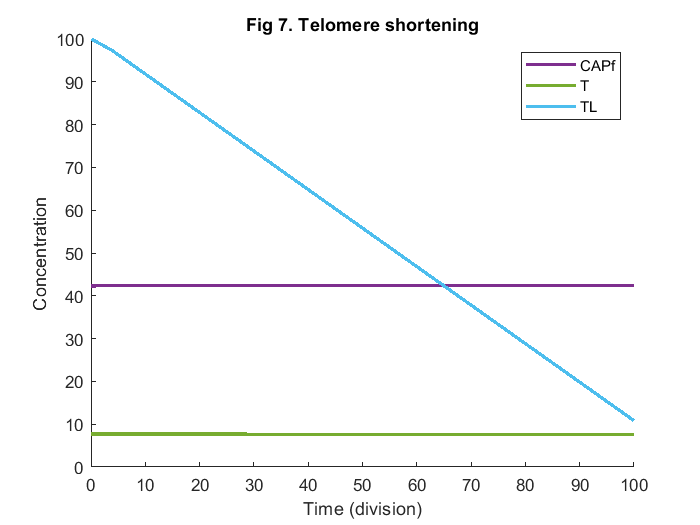

% Figure 7

s_CAPf = 0.25; s_CAPb = 20; s_T = 300; s_SSL = 20; s_Oex = 0.5; s_Oin = 0.5; s_TL = 0.1;
xin = [169.267; 0.999882; 0.0256461; 2.00363; 0; 0; 1000.51];
%xin = [170; 0; 0.05; 1; 0; 0; 1000];
time = 0:0.01:100;
K3 = 5;
K5 = 0;
K6 = 8;
B = 8;
[tSol, xSol] = ode45(@(t,x) extendedModel(t,x,K3,K5,K6,B), time, xin);
figure(7); hold on;
a1 = plot(tSol,s_CAPf*xSol(:,1),'LineWidth',2); M1 = "CAPf";
a3 = plot(tSol,s_T*xSol(:,3),'LineWidth',2); M3 = "T";
a7 = plot(tSol,s_TL*xSol(:,7),'LineWidth',2); M7 = "TL";
legend([a1 a3 a7], [M1 M3 M7]);
xlabel("Time (division)");
ylabel("Concentration");

title('Fig 7. Telomere shortening');
% xlim([0 100]);
ylim([0 100]);

Figure 8

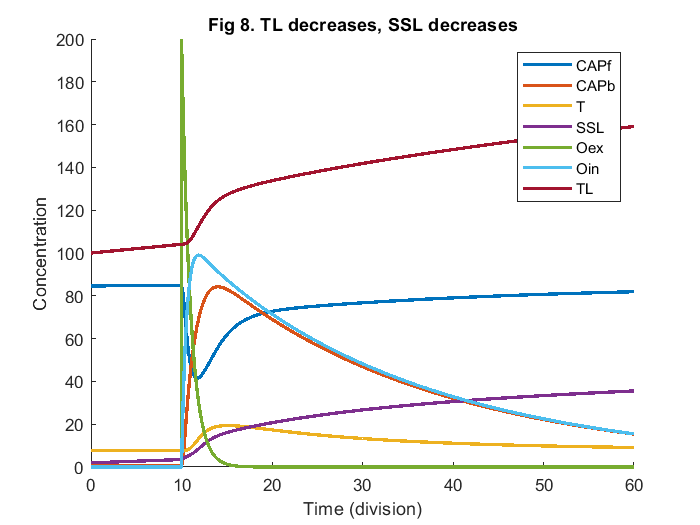

s_CAPf = 0.50; s_CAPb = 0.5; s_T = 300; s_SSL = 1; s_Oex = 0.5; s_Oin = 0.5; s_TL = 0.1;
%xin = [169.1246; 0.9998; 0.0256461; 2.00363; 400; 0; 1000.00];
time = 0:0.01:50;
KDEG = 1;
K3 = 0.01;
K5 = 500;
K6 = 10;
B = 0;

%[tSol, xSol] = ode45(@(t,x) extendModel(t,x,K3,K5,K6,B), time, xin);


tS = {}; xS = {};
xin = [169.1246; 0.9998; 0.0256461; 2.00363; 0; 0; 1000.00];
%xin = [169.1246; 0; 0.0256461; 1.00363; 0; 0; 1000.00];
%xin = [170; 0; 0.05; 1; 0; 0; 1000];
i = 0;
time = i:0.1:i+10;
% Ode function
[tS{i+1}, xS{i+1}] = ode45(@(t,x) extendModel(t,x,K3,K5,K6,B,KDEG), time, xin);

tp = cell2mat(tS(:));
xp = cell2mat(xS(:));

ss_CAPf = xp(end,1);
ss_CAPb = xp(end,2);
ss_T = xp(end,3);
ss_SSL = xp(end,4);
ss_TL = xp(end,7);

xin = [ss_CAPf; ss_CAPb; ss_T; ss_SSL; 400; 0; ss_TL];

%xin = [169.1246; 0.9998; 0.0256461; 2.00363; 400; 0; 1000.00];
i = 10;
time = i:0.1:i+50;
[tS{i+1}, xS{i+1}] = ode45(@(t,x) extendModel(t,x,K3,K5,K6,B,KDEG), time, xin);

    
tp = cell2mat(tS(:));
xp = cell2mat(xS(:));


figure(8); hold on;
a1 = plot(tp,s_CAPf*xp(:,1),'LineWidth',2); M1 = "CAPf";
a2 = plot(tp,s_CAPb*xp(:,2),'LineWidth',2); M2 = "CAPb";
a3 = plot(tp,s_T*xp(:,3),'LineWidth',2); M3 = "T";
a4 = plot(tp,s_SSL*xp(:,4),'LineWidth',2); M4 = "SSL";
a5 = plot(tp,s_Oex*xp(:,5),'LineWidth',2); M5 = "Oex";
a6 = plot(tp,s_Oin*xp(:,6),'LineWidth',2); M6 = "Oin";
a7 = plot(tp,s_TL*xp(:,7),'LineWidth',2); M7 = "TL";
legend([a1 a2 a3 a4 a5 a6 a7], [M1 M2 M3 M4 M5 M6 M7]);
xlabel("Time (division)");
ylabel("Concentration");
title('Fig 8. TL decreases, SSL decreases');

Figure 9

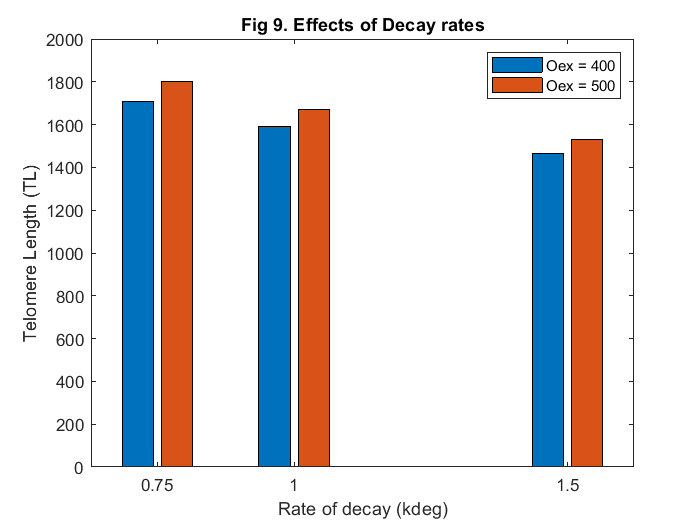

% Figure 9

% After substituting different values for 

kdeg_arr = [1.5 1 0.75];
TL_kdeg = zeros(2,3);
for i=1:3
    xin = [ss_CAPf; ss_CAPb; ss_T; ss_SSL; 400; 0; ss_TL];
    [tSol, xSol] = ode45(@(t,x) extendModel(t,x,K3,K5,K6,B,kdeg_arr(i)), time, xin);
    TL_kdeg(1,i) = xSol(end,7);
    xin = [ss_CAPf; ss_CAPb; ss_T; ss_SSL; 500; 0; ss_TL];
    [tSol, xSol] = ode45(@(t,x) extendModel(t,x,K3,K5,K6,B,kdeg_arr(i)), time, xin);
    TL_kdeg(2,i) = xSol(end,7);
    
end

figure(9);
x = [1.5 1 0.75];
b = bar(x,TL_kdeg);
xticks([0.75 1 1.5]);
label = {'Oex = 400','Oex = 500'};
legend(b,label);
xlabel("Rate of decay (kdeg)");
ylabel("Telomere Length (TL)");
title('Fig 9. Effects of Decay rates');

**Functions**

function heavyside = H(x)
    if(x<=0)
        heavyside = 0;
    else
        heavyside = 1;
    end
end

% Function 
function fx = extendedModel(t,x,K3,K5,K6,B)

%Parameters
k1 = 100;
k2 = 0.1;
k3 = K3;
k4 = 0;
k5 = K5;
k6 = K6;
PCAP = 100;
PT = 5;
kdeg = 1;
kdiff = 1;
NT = 1;
Len = 0;
BL = B;
%Oli = 100;
%Oex = 400;

CAPf = x(1); CAPb = x(2); T = x(3); SSL = x(4); Oex = x(5); Oin = x(6); TL = x(7);

dCAPfdt = k1/(1 + (CAPf/PCAP)^3) + (k4-k2)*CAPf - k3*CAPf*(NT + Oin - CAPb)*H(SSL-2) ;
dCAPbdt = k3*CAPf*(NT + Oin - CAPb)*H(SSL-2) - (k4+k2)*CAPb ;
dTdt = k1/(1 + (CAPf/PT)^3) -k2*T;
dSSLdt = (k5*T - k6)*(NT + Oin - CAPb)/(NT + Oin);
dOexdt = -kdeg*Oex ;
dOindt = kdiff*(Oex - Oin*(NT + Oin - CAPb)/(NT + Oin));

if(SSL-2>0)
    Len = 1;
elseif(SSL-2<=0)
    Len = -1;
end
dTLdt = Len-BL ;

fx = [dCAPfdt; dCAPbdt; dTdt; dSSLdt; dOexdt; dOindt; dTLdt];

end


% Function particularly for Figure 8
function fx = extendModel(t,x,K3,K5,K6,B,KDEG)

%Parameters
k1 = 100;
k2 = 0.1;
k3 = K3;
k4 = 0;
k5 = K5;
k6 = K6;
PCAP = 100;
PT = 5;
kdeg = KDEG;
kdiff = 1;
NT = 1;
Len = 0;
BL = B;
%Oli = 100;
%Oex = 400;

CAPf = x(1); CAPb = x(2); T = x(3); SSL = x(4); Oex = x(5); Oin = x(6); TL = x(7);

dCAPfdt = k1/(1 + (CAPf/PCAP)^3) + (k4-k2)*CAPf - k3*CAPf*(NT + Oin - CAPb)*H(SSL-2) ;
dCAPbdt = k3*CAPf*(NT + Oin - CAPb)*H(SSL-2) - (k4+k2)*CAPb ;
dTdt = k1/(1 + (CAPf/PT)^3) -k2*T;
dSSLdt = (k5*T - k6)*(NT + Oin - CAPb)/(NT + Oin);
dOexdt = -kdeg*Oex ;
dOindt = kdiff*(Oex - Oin*(NT + Oin - CAPb)/(NT + Oin));

if(SSL-2>0)
    Len = 1;
elseif(SSL-2<=0)
    Len = -1;
end

% For other figures
%dTLdt = Len-BL;

% For fig 9 use this condition
%dTLdt = SSL-BL;

% For figure 8 ue this condition
dTLdt = k1/(1 + (CAPf/PCAP)^6) - BL ;

fx = [dCAPfdt; dCAPbdt; dTdt; dSSLdt; dOexdt; dOindt; dTLdt];

end
